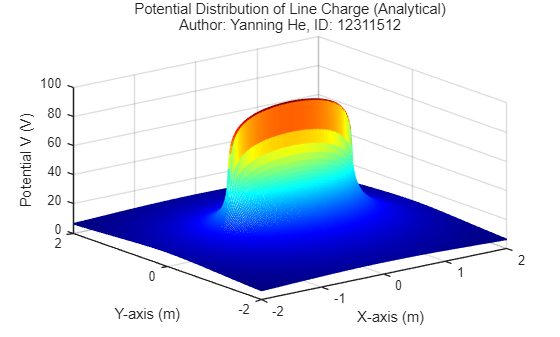

clc; clear; close all;

%% 1. Parameter Initialization & Domain Setup
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
xm = 2; ym = 2;         % Define observation domain boundaries (meters)

% Generate calculation grid for the 2D plane
% Increasing resolution to 200 for smoother gradient transitions
x = linspace(-xm, xm, 200); 
y = linspace(-ym, ym, 200); 
[X, Y] = meshgrid(x, y);

%% 2. Analytical Solution (Integral Method)
% Based on the integral formula: V = k*p * ln[ (r1) / (r2) ]
% where the integration is performed along the segment x' = [-1, 1]
r1 = 1 - X + sqrt((1 - X).^2 + Y.^2);
r2 = -1 - X + sqrt((-1 - X).^2 + Y.^2);
V = k .* p .* log(r1 ./ r2);

%% 3. Plotting 3D Potential Distribution
figure('Color', 'w');   % Set background to white for report compatibility
mesh(X, Y, V);
colormap jet;           % Apply heat-map color scheme
grid on;
xlabel('X-axis (m)'); ylabel('Y-axis (m)'); zlabel('Potential V (V)');
% Title formatted as a cell array for multi-line display
title({'Potential Distribution of Line Charge (Analytical)', ...
       'Author: Yanning He, ID: 12311512'}); 
saveas(gcf, 'figure1.1.jpg');


%% 4. Plotting Equipotential Contours
figure('Color', 'w');
V_levels = linspace(0, 100, 50); % Define contour density
[C, h] = contour(X, Y, V, V_levels, 'LineWidth', 1);

hold on;

% Highlight the linear charge source (Red solid line)
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); 
grid on;
axis equal;             % Maintain 1:1 aspect ratio to avoid spatial distortion
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({'Equipotential Contours (Analytical Method)', ...
       'Author: Yanning He, ID: 12311512'});
saveas(gcf, 'figure1.2.jpg');


%% 5. Plotting Composite Map (Electric Field Lines & Potential)
% Calculate electric field intensity E = -grad(V)
[Ex, Ey] = gradient(-V);

figure('Color', 'w');
hold on;


% Define seed points for streamlines to ensure uniform distribution
xs_seed = -1.2:0.2:1.2;
ys_seed_pos = 0.05 * ones(size(xs_seed));
ys_seed_neg = -0.05 * ones(size(xs_seed));

% Generate streamlines to represent the electric field
h1 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_pos);
h2 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_neg);
set([h1, h2], 'LineWidth', 2, 'Color', [0.1, 0.4, 0.1]); 

% Overlay contours and the physical charge location
contour(X, Y, V, V_levels, 'LineColor', 'b'); 
plot([-1, 1], [0, 0], 'r', 'LineWidth', 4); 

grid on;
axis equal;             % Critical for preserving orthogonality of E and V lines
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({'Electric Field Lines & Equipotential Mapping', ...
       'Author: Yanning He, ID: 12311512'});
saveas(gcf, 'figure1.3.jpg');

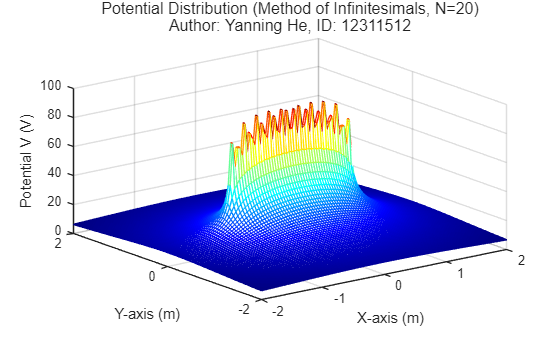

clc; clear; close all;

%% 1. Parameter Initialization & Discretization Setup
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
L_total = 2;            % Total length of the charge (from -1 to 1)
N = 20;                 % Number of segments (Change to 50 or 100 for other tasks)
dL = L_total / N;       % Length of each infinitesimal element
dQ = p * dL;            % Charge of each infinitesimal element

% Observation domain setup
xm = 2; ym = 2;
x = linspace(-xm, xm, 100);
y = linspace(-ym, ym, 100);
[X, Y] = meshgrid(x, y);

%% 2. Method of Infinitesimals (Numerical Summation)
V = zeros(size(X));     % Initialize potential matrix
for i = 1:N
    % Calculate the center position of each segment
    % Start at -1, offset by half a segment, then increment by dL
    x_pos = -1 + (i - 0.5) * dL; 
    
    % Distance from the segment center to all grid points
    R = sqrt((X - x_pos).^2 + Y.^2);
    
    % Superposition of potential: V = sum( k * dQ / R )
    V = V + (k * dQ ./ R);
end

%% 3. Plotting 3D Potential Distribution
figure('Color', 'w');
mesh(X, Y, V);
colormap jet;
grid on;
xlabel('X-axis (m)'); ylabel('Y-axis (m)'); zlabel('Potential V (V)');
title({['Potential Distribution (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure2.1.jpg');

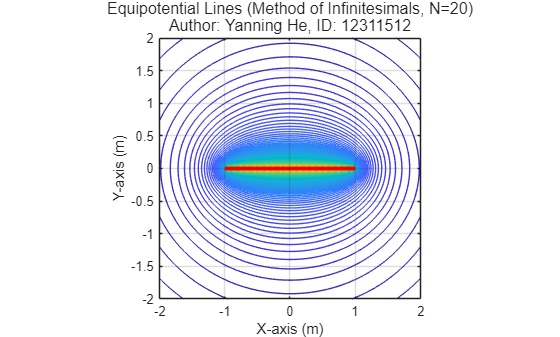


%% 4. Plotting Equipotential Contours
figure('Color', 'w');
V_levels = linspace(0, 100, 101); % Contour levels from 0V to 100V
contour(X, Y, V, V_levels);
hold on;
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); % Represent the physical line charge
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Equipotential Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure2.2.jpg');

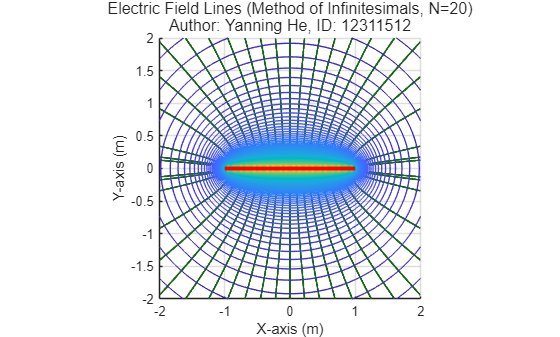


%% 5. Plotting Electric Field Lines
[Ex, Ey] = gradient(-V); % E-field is the negative gradient of potential
xs_seed = -1.2:0.1:1.2;  % Starting points for streamlines
ys_seed_pos = 0.05 * ones(size(xs_seed));
ys_seed_neg = -0.05 * ones(size(xs_seed));

figure('Color', 'w');
hold on;
% Draw streamlines representing the direction of the electric field
h1 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_pos);
h2 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_neg);
set([h1, h2], 'LineWidth', 1.5, 'Color', [0.1, 0.4, 0.1]);

contour(X, Y, V, V_levels); % Overlay equipotential lines
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); 
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Electric Field Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure2.3.jpg');

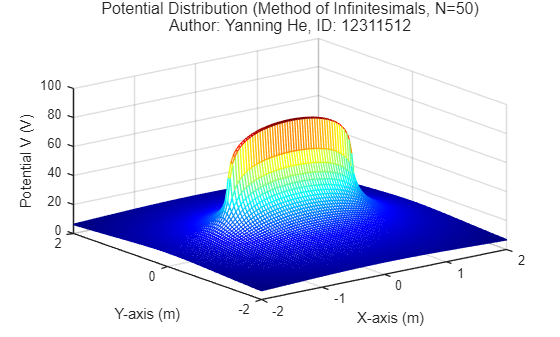

clc; clear; close all;

%% 1. Parameter Initialization & Discretization Setup
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
L_total = 2;            % Total length of the charge (from -1 to 1)
N = 50;                 % Number of segments (Change to 50 or 100 for other tasks)
dL = L_total / N;       % Length of each infinitesimal element
dQ = p * dL;            % Charge of each infinitesimal element

% Observation domain setup
xm = 2; ym = 2;
x = linspace(-xm, xm, 100);
y = linspace(-ym, ym, 100);
[X, Y] = meshgrid(x, y);

%% 2. Method of Infinitesimals (Numerical Summation)
V = zeros(size(X));     % Initialize potential matrix
for i = 1:N
    % Calculate the center position of each segment
    % Start at -1, offset by half a segment, then increment by dL
    x_pos = -1 + (i - 0.5) * dL; 
    
    % Distance from the segment center to all grid points
    R = sqrt((X - x_pos).^2 + Y.^2);
    
    % Superposition of potential: V = sum( k * dQ / R )
    V = V + (k * dQ ./ R);
end

%% 3. Plotting 3D Potential Distribution
figure('Color', 'w');
mesh(X, Y, V);
colormap jet;
grid on;
xlabel('X-axis (m)'); ylabel('Y-axis (m)'); zlabel('Potential V (V)');
title({['Potential Distribution (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure3.1.jpg');

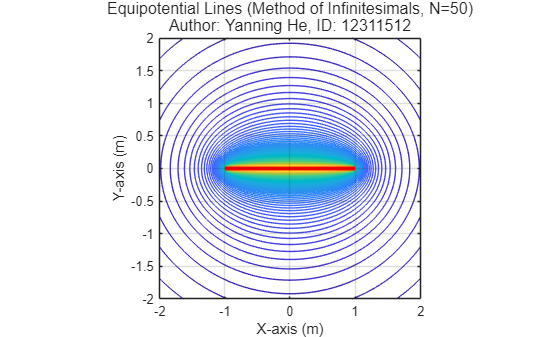


%% 4. Plotting Equipotential Contours
figure('Color', 'w');
V_levels = linspace(0, 100, 101); % Contour levels from 0V to 100V
contour(X, Y, V, V_levels);
hold on;
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); % Represent the physical line charge
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Equipotential Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure3.2.jpg');

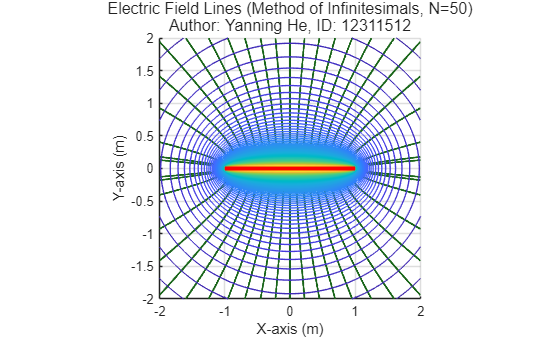


%% 5. Plotting Electric Field Lines
[Ex, Ey] = gradient(-V); % E-field is the negative gradient of potential
xs_seed = -1.2:0.1:1.2;  % Starting points for streamlines
ys_seed_pos = 0.05 * ones(size(xs_seed));
ys_seed_neg = -0.05 * ones(size(xs_seed));

figure('Color', 'w');
hold on;
% Draw streamlines representing the direction of the electric field
h1 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_pos);
h2 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_neg);
set([h1, h2], 'LineWidth', 1.5, 'Color', [0.1, 0.4, 0.1]);

contour(X, Y, V, V_levels); % Overlay equipotential lines
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); 
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Electric Field Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure3.3.jpg');

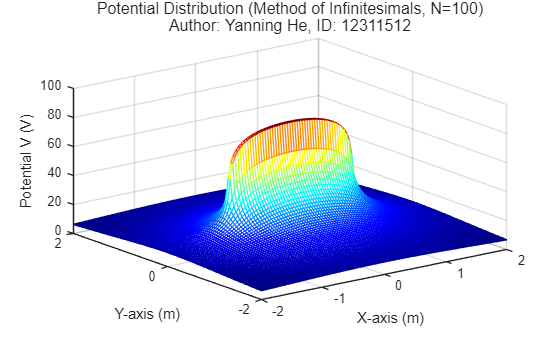

clc; clear; close all;

%% 1. Parameter Initialization & Discretization Setup
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
L_total = 2;            % Total length of the charge (from -1 to 1)
N = 100;                 % Number of segments (Change to 50 or 100 for other tasks)
dL = L_total / N;       % Length of each infinitesimal element
dQ = p * dL;            % Charge of each infinitesimal element

% Observation domain setup
xm = 2; ym = 2;
x = linspace(-xm, xm, 100);
y = linspace(-ym, ym, 100);
[X, Y] = meshgrid(x, y);

%% 2. Method of Infinitesimals (Numerical Summation)
V = zeros(size(X));     % Initialize potential matrix
for i = 1:N
    % Calculate the center position of each segment
    % Start at -1, offset by half a segment, then increment by dL
    x_pos = -1 + (i - 0.5) * dL; 
    
    % Distance from the segment center to all grid points
    R = sqrt((X - x_pos).^2 + Y.^2);
    
    % Superposition of potential: V = sum( k * dQ / R )
    V = V + (k * dQ ./ R);
end

%% 3. Plotting 3D Potential Distribution
figure('Color', 'w');
mesh(X, Y, V);
colormap jet;
grid on;
xlabel('X-axis (m)'); ylabel('Y-axis (m)'); zlabel('Potential V (V)');
title({['Potential Distribution (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure4.1.jpg');

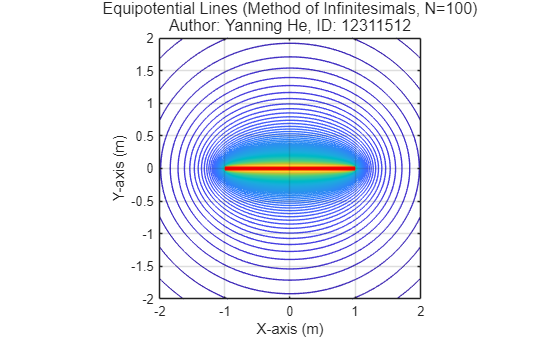


%% 4. Plotting Equipotential Contours
figure('Color', 'w');
V_levels = linspace(0, 100, 101); % Contour levels from 0V to 100V
contour(X, Y, V, V_levels);
hold on;
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); % Represent the physical line charge
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Equipotential Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize', 12);
saveas(gcf, 'figure4.2.jpg');

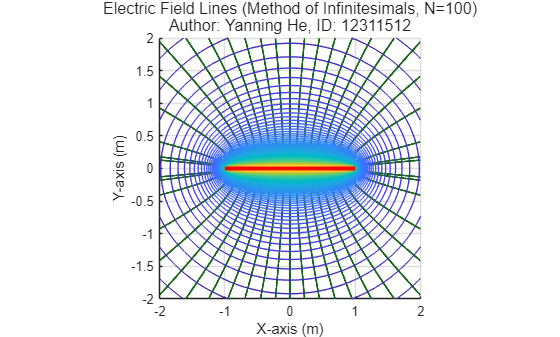


%% 5. Plotting Electric Field Lines
[Ex, Ey] = gradient(-V); % E-field is the negative gradient of potential
xs_seed = -1.2:0.1:1.2;  % Starting points for streamlines
ys_seed_pos = 0.05 * ones(size(xs_seed));
ys_seed_neg = -0.05 * ones(size(xs_seed));

figure('Color', 'w');
hold on;
% Draw streamlines representing the direction of the electric field
h1 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_pos);
h2 = streamline(X, Y, Ex, Ey, xs_seed, ys_seed_neg);
set([h1, h2], 'LineWidth', 1.5, 'Color', [0.1, 0.4, 0.1]);

contour(X, Y, V, V_levels); % Overlay equipotential lines
plot([-1, 1], [0, 0], 'r', 'LineWidth', 3); 
grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title({['Electric Field Lines (Method of Infinitesimals, N=', num2str(N), ')'], ...
       'Author: Yanning He, ID: 12311512'}, 'FontSize',12);
saveas(gcf, 'figure4.3.jpg');

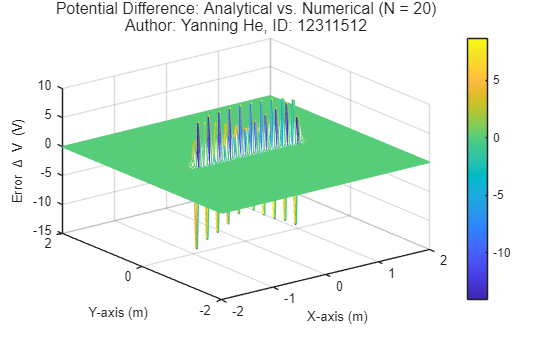

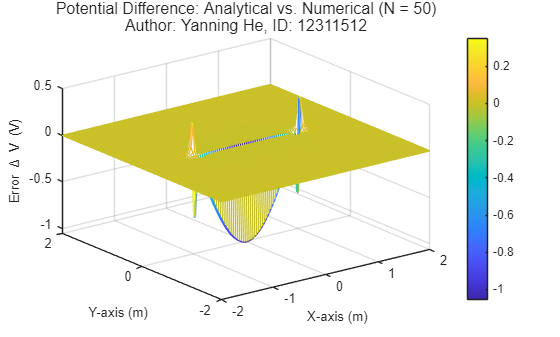

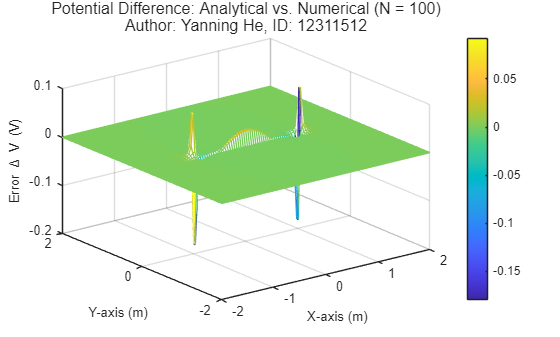

clc; clear; close all;

%% 1. Parameter Initialization
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
xm = 2; ym = 2;         % Observation domain boundaries (m)

% Generate calculation grid
x = linspace(-xm, xm, 100);
y = linspace(-ym, ym, 100);
[X, Y] = meshgrid(x, y);

%% 2. Reference Potential (Analytical Integral Method)
% Theoretical potential used as the "True Value" for error comparison
r1 = 1 - X + sqrt((1 - X).^2 + Y.^2);
r2 = -1 - X + sqrt((-1 - X).^2 + Y.^2);
V_true = k .* p .* log(r1 ./ r2);

%% 3. Numerical Approximation & Error Analysis
% Array containing the different segment counts to be tested
segment_counts = [20, 50, 100];
figure_indices = [1, 2, 3];

for j = 1:length(segment_counts)
    N = segment_counts(j);
    dL = 2 / N;         % Length of each segment (Total length = 2m)
    dQ = p * dL;        % Charge per segment
    V_num = zeros(size(X)); % Initialize numerical potential matrix
    
    % Method of Infinitesimals: Summation of discrete point charges
    for i = 1:N
        % Identify the center position of the current segment
        x_pos = -1 + (i - 0.5) * dL;
        R = sqrt((X - x_pos).^2 + Y.^2);
        V_num = V_num + (k * dQ ./ R);
    end
    
    % Calculate the Local Absolute Error (Difference)
    V_diff = V_true - V_num;
    
    %% 4. Visualization of Potential Difference (Error)
    figure('Color', 'w');
    mesh(X, Y, V_diff);
    colorbar;           % Add color scale for quantitative reference
    grid on;
    
    % Formatting labels and titles
    xlabel('X-axis (m)', 'FontSize', 10);
    ylabel('Y-axis (m)', 'FontSize', 10);
    zlabel('Error \Delta V (V)', 'FontSize', 10);
    
    % Dynamic title including segment count and student info
    title_str = {['Potential Difference: Analytical vs. Numerical (N = ', num2str(N), ')'], ...
                 'Author: Yanning He, ID: 12311512'};
    title(title_str, 'FontSize', 12);
    
    % Save the result for the report
    file_name = sprintf('figure5.%d.jpg', figure_indices(j));
    saveas(gcf, file_name);
end


fprintf('Error analysis plots for N = 20, 50, and 100 have been generated.\n');

Error analysis plots for N = 20, 50, and 100 have been generated.


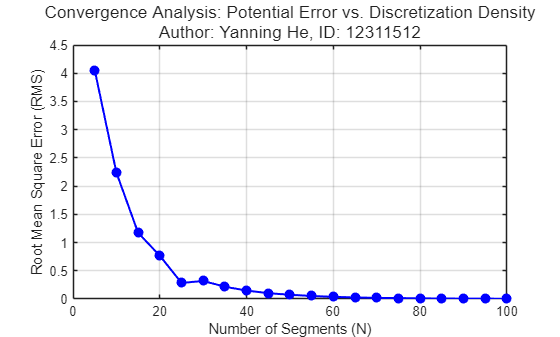

clc; clear; close all;

%% 1. Parameter Initialization & Reference Field
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
xm = 2; ym = 2;         % Observation domain boundaries (m)

% Generate calculation grid (100x100 = 10,000 points)
n_points = 100;
x_vec = linspace(-xm, xm, n_points);
y_vec = linspace(-ym, ym, n_points);
[X, Y] = meshgrid(x_vec, y_vec);

% Calculate reference potential using the Analytical Integral Method
r1 = 1 - X + sqrt((1 - X).^2 + Y.^2);
r2 = -1 - X + sqrt((-1 - X).^2 + Y.^2);
V_analytical = k .* p .* log(r1 ./ r2);

%% 2. Convergence Study: Error vs. Number of Segments
segments = 5:5:100;     % Array of segment counts to test
rms_errors = zeros(size(segments)); % Pre-allocate array for efficiency

for idx = 1:length(segments)
    N = segments(idx);
    dL = 2 / N;         % Length of each discrete segment
    dQ = p * dL;        % Charge per segment
    V_numerical = zeros(size(X)); 
    
    % Perform numerical summation for N segments
    for j = 1:N
        x_pos = -1 + (j - 0.5) * dL; % Center of the j-th segment
        R = sqrt((X - x_pos).^2 + Y.^2);
        V_numerical = V_numerical + (k * dQ ./ R);
    end
    
    % Calculate the Root Mean Square (RMS) Error
    % RMS = sqrt( sum( (V_true - V_num)^2 ) / total_points )
    error_sq = (V_analytical - V_numerical).^2;
    rms_errors(idx) = sqrt(sum(error_sq(:)) / numel(X));
end

%% 3. Visualization of Convergence Results
figure('Color', 'w');
plot(segments, rms_errors, '-bo', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

% Labeling and Titling for Scientific Reporting
xlabel('Number of Segments (N)', 'FontSize', 11);
ylabel('Root Mean Square Error (RMS)', 'FontSize', 11);
title_str = {['Convergence Analysis: Potential Error vs. Discretization Density'], ...
             'Author: Yanning He, ID: 12311512'};
title(title_str, 'FontSize', 13);

% Save the convergence plot
saveas(gcf, 'figure5.4.jpg');


fprintf('Convergence analysis complete. RMS error values have been plotted.\n');

Convergence analysis complete. RMS error values have been plotted.


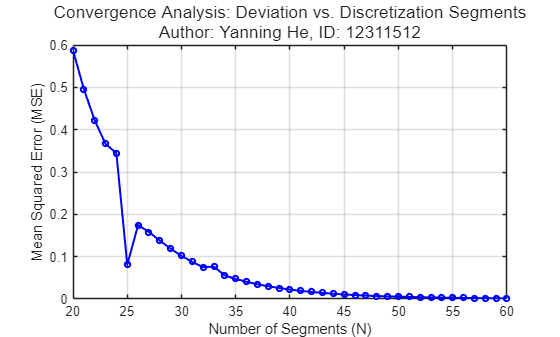

clc; clear; close all;

%% 1. Physical Constants & Grid Initialization
k = 9e9;                % Electrostatic constant (N·m^2/C^2)
p = 1e-9;               % Linear charge density (C/m)
xm = 2; ym = 2;         % Observation domain boundaries (meters)

% Generate calculation grid (100x100 resolution)
grid_res = 100;
x_coords = linspace(-xm, xm, grid_res);
y_coords = linspace(-ym, ym, grid_res);
[X, Y] = meshgrid(x_coords, y_coords);

%% 2. Reference Field: Analytical Potential (Integral Method)
% Theoretical potential used as the "Ground Truth"
r1 = 1 - X + sqrt((1 - X).^2 + Y.^2);
r2 = -1 - X + sqrt((-1 - X).^2 + Y.^2);
V_analytical = k .* p .* log(r1 ./ r2);

%% 3. Convergence Loop: Segment Range 20 to 60
segment_range = 20:1:60;
rms_errors = zeros(size(segment_range)); % Pre-allocate for performance

for idx = 1:length(segment_range)
    N = segment_range(idx);
    dL = 2 / N;         % Width of each discrete element
    dQ = p * dL;        % Charge per element
    V_numerical = zeros(size(X));
    
    % Accumulate potential from each infinitesimal segment
    for j = 1:N
        % Precise midpoint calculation for the j-th segment in range [-1, 1]
        x_pos = -1 + (j - 0.5) * dL;
        R = sqrt((X - x_pos).^2 + Y.^2);
        V_numerical = V_numerical + (k * dQ ./ R);
    end
    
    % Calculate Mean Squared Error (MSE) / Deviation
    % Using the user-defined normalization factor (1/10000)
    error_sq = (V_analytical - V_numerical).^2;
    rms_errors(idx) = sum(error_sq(:)) / numel(X);
end

%% 4. Results Visualization & Reporting
figure('Color', 'w');
plot(segment_range, rms_errors, '-bo', 'LineWidth', 1.5, 'MarkerSize', 4);
grid on;

% Academic labeling and student identification
xlabel('Number of Segments (N)', 'FontSize', 11);
ylabel('Mean Squared Error (MSE)', 'FontSize', 11);
title_header = 'Convergence Analysis: Deviation vs. Discretization Segments';
author_info = 'Author: Yanning He, ID: 12311512';
title({title_header, author_info}, 'FontSize', 13);

% Exporting result for technical report
saveas(gcf, 'figure5.5.jpg');


fprintf('High-resolution convergence plot (N=20-60) has been generated and saved.\n');

High-resolution convergence plot (N=20-60) has been generated and saved.


clc; clear; close all;

k = 9e9;
rho = 1e-9;
xm = 2; ym = 2;
n_points = 100;

x = linspace(-xm, xm, n_points);
y = linspace(-ym, ym, n_points);
[X, Y] = meshgrid(x, y);

% Analytical / continuous solution
r1 = 1 - X + sqrt((1 - X).^2 + Y.^2);
r2 = -1 - X + sqrt((-1 - X).^2 + Y.^2);
V_true = k * rho * log(r1 ./ r2);

segment_counts = [20, 50, 100];

N_col = [];
dL_col = [];
dQ_col = [];
RMS_col = [];
MSE_col = [];
MAE_col = [];
MaxAbs_col = [];
RelRMS_col = [];

V_true_rms = sqrt(mean(V_true(:).^2));

for N = segment_counts
    dL = 2 / N;
    dQ = rho * dL;
    V_num = zeros(size(X));

    for i = 1:N
        x_pos = -1 + (i - 0.5) * dL;
        R = sqrt((X - x_pos).^2 + Y.^2);
        V_num = V_num + k * dQ ./ R;
    end

    diff = V_true - V_num;

    N_col(end+1,1) = N;
    dL_col(end+1,1) = dL;
    dQ_col(end+1,1) = dQ;
    RMS_col(end+1,1) = sqrt(mean(diff(:).^2));
    MSE_col(end+1,1) = mean(diff(:).^2);
    MAE_col(end+1,1) = mean(abs(diff(:)));
    MaxAbs_col(end+1,1) = max(abs(diff(:)));
    RelRMS_col(end+1,1) = RMS_col(end) / V_true_rms * 100;
end

T = table(N_col, dL_col, dQ_col, RMS_col, MSE_col, MAE_col, MaxAbs_col, RelRMS_col, ...
    'VariableNames', {'N','dL_m','dQ_C','RMS_error_V','MSE_V2','MAE_V','MaxAbsError_V','RelativeRMS_percent'});

disp(T);

     N     dL_m    dQ_C     RMS_error_V      MSE_V2        MAE_V       MaxAbsError_V    RelativeRMS_percent
    ___    ____    _____    ___________    __________    __________    _____________    ___________________

     20     0.1    1e-10       0.76661        0.58769      0.076542        14.131              4.0418      
     50    0.04    4e-11      0.075095      0.0056393     0.0078945        1.0568             0.39592      
    100    0.02    2e-11     0.0049694     2.4695e-05    0.00054732       0.18012              0.0262      




% 如需生成 CSV，把本脚本放到你允许写入的位置后运行：
writetable(T, 'lab2_error_summary.csv');

points = [-2 -2;
          -2 -1.5;
          -2 -1;
          -2 -0.5];

segment_counts = [100, 50, 20];

Point = ["P1"; "P2"; "P3"; "P4"];
x_m = points(:,1);
y_m = points(:,2);
Distance_to_A_m = sqrt((x_m + 1).^2 + y_m.^2);

V_continuous_V = zeros(4,1);
V_N100_V = zeros(4,1);
V_N50_V = zeros(4,1);
V_N20_V = zeros(4,1);

k = 9e9;
rho = 1e-9;

for idx = 1:4
    X = x_m(idx);
    Y = y_m(idx);

    r1 = 1 - X + sqrt((1 - X)^2 + Y^2);
    r2 = -1 - X + sqrt((-1 - X)^2 + Y^2);
    V_continuous_V(idx) = k * rho * log(r1 / r2);

    values = zeros(1,3);
    for s = 1:3
        N = segment_counts(s);
        dL = 2 / N;
        dQ = rho * dL;
        V_num = 0;

        for i = 1:N
            x_pos = -1 + (i - 0.5) * dL;
            R = sqrt((X - x_pos)^2 + Y^2);
            V_num = V_num + k * dQ / R;
        end

        values(s) = V_num;
    end

    V_N100_V(idx) = values(1);
    V_N50_V(idx) = values(2);
    V_N20_V(idx) = values(3);
end

T = table(Point, x_m, y_m, Distance_to_A_m, ...
    V_continuous_V, V_N100_V, V_N50_V, V_N20_V);

disp(T);

    Point    x_m    y_m     Distance_to_A_m    V_continuous_V    V_N100_V    V_N50_V    V_N20_V
    _____    ___    ____    _______________    ______________    ________    _______    _______

    "P1"     -2       -2        2.2361              6.422          6.422     6.4219     6.4219 
    "P2"     -2     -1.5        1.8028             7.3664         7.3664     7.3664     7.3661 
    "P3"     -2       -1        1.4142             8.4337         8.4336     8.4335     8.4327 
    "P4"     -2     -0.5         1.118             9.4333         9.4332     9.4329      9.431 




% 如需生成 CSV：
writetable(T, 'lab2_sample_points.csv');
